A square wave of length 1 s (𝑡 ∈ [0, 1] s) at 50 Hz with sampling frequency 10 kHz

fs = 10000;
t = 0:1/fs:1;
x = square(2*pi*50*t);

a. Using the LPF function you designed, filter this signal with fc = 60 Hz and fc = 200 Hz

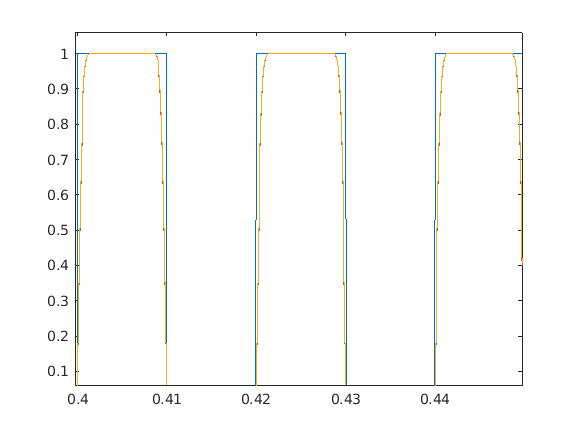

ylo1 = my_LPF(x,fs,60);
ylo2 = my_LPF(x,fs,200);

plot(t,x);
hold on;
plot(t,ylo1); 
plot(t,ylo2);

axis([0.4 0.45 0 1])

hold off;

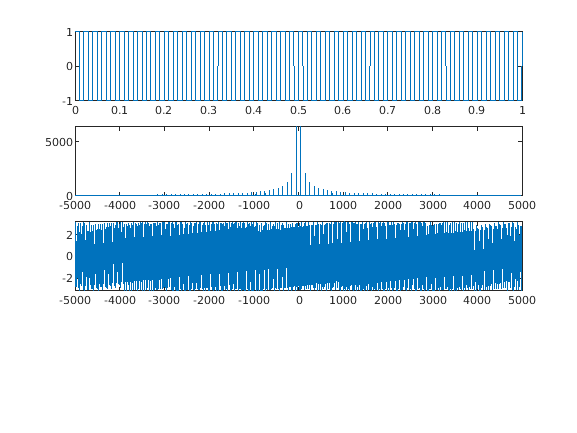

X = fft(x); % This statement computes Fourier transform of x
n = length(x); % length(x) gives the array length of signal x
c = (-1 * fs) / 2:fs / n:fs / 2 - fs / n; % It generates the frequency series to plot X in frequency domain
subplot(4, 1, 1),plot(t,x); % This subplot shows the signal x vs. time series t
subplot(4, 1 ,2),plot(c,fftshift(abs(X))); % This subplot shows the Fourier spectrum of x with zero frequency component shifted to center
subplot(4, 1, 3),plot(c,angle(X)); % This subplot shows the phase distribution of X (Fourier transform of x)

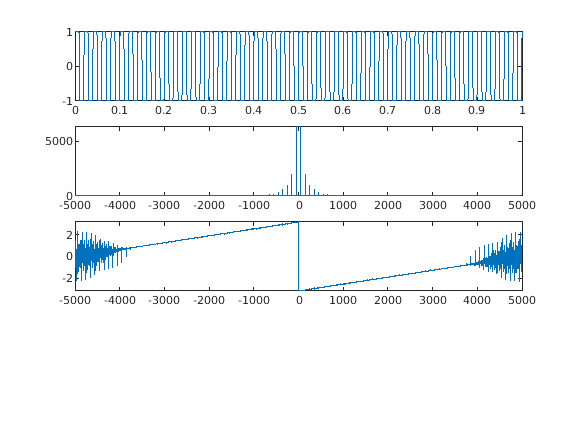

YLO1 = fft(ylo1); % This statement computes Fourier transform of ylo1
n1 = length(ylo1); %  gives the array length of signal ylo1
c = (-1 * fs) / 2:fs / n1:fs / 2 - fs / n1; 
subplot(4, 1, 1),plot(t,ylo1); % This subplot shows the signal ylo1 vs. time series t
subplot(4, 1 ,2),plot(c,fftshift(abs(YLO1))); 

subplot(4, 1, 3),plot(c,angle(YLO1)); 

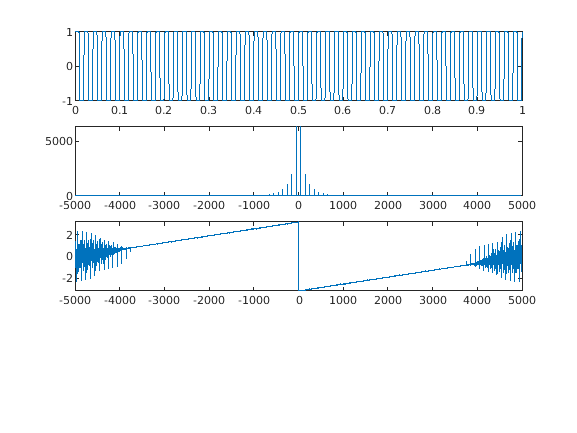

YLO2 = fft(ylo2); % This statement computes Fourier transform of ylo2
n2 = length(ylo2);
c = (-1 * fs) / 2:fs / n2:fs / 2 - fs / n2; 
subplot(4, 1, 1),plot(t,ylo2);
subplot(4, 1 ,2),plot(c,fftshift(abs(YLO2)));
subplot(4, 1, 3),plot(c,angle(YLO2)); 

b. Using the HPF function you designed, filter this signal with fc = 100 Hz

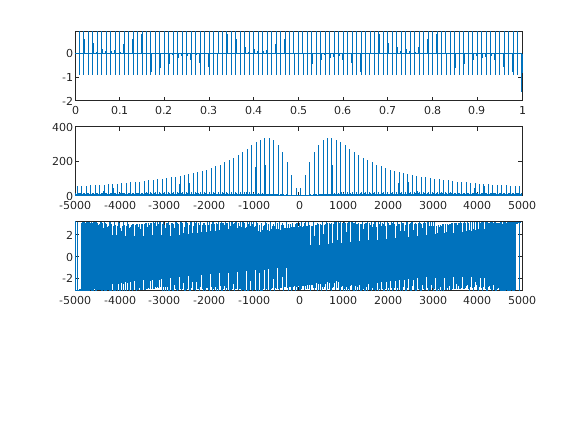

yhi = my_HPF(x,fs,100);
YHI = fft(yhi); 
n = length(yhi); 
c = (-1 * fs) / 2:fs / n:fs / 2 - fs / n; 
subplot(4, 1, 1),plot(t,yhi); 
subplot(4, 1 ,2),plot(c,fftshift(abs(YHI))); 
subplot(4, 1, 3),plot(c,angle(YHI)); 

c. Using the BPF function you designed, filter this signal with fclo = 100 Hz and fchi = 200 Hz

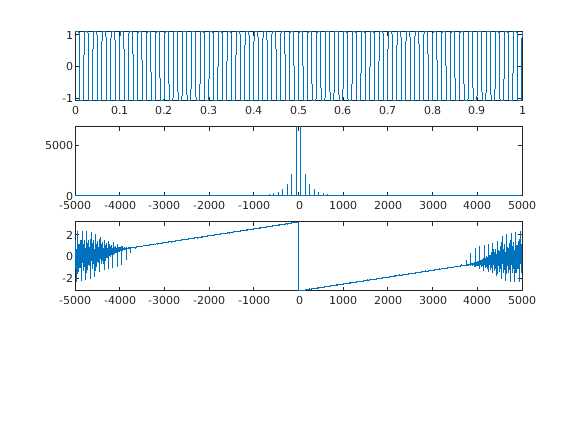

ybp = my_BPF(x,fs,100,200);
YBP = fft(ybp); 
n = length(ybp); 
c = (-1 * fs) / 2:fs / n:fs / 2 - fs / n; 
subplot(4, 1, 1),plot(t,ybp); 
subplot(4, 1 ,2),plot(c,fftshift(abs(YBP)));  
subplot(4, 1, 3),plot(c,angle(YBP)); 